# **Repetition Codes in Quantum Error Correction (QEC)**

**Matteo Rossi**

## **Introduction**

Quantum computing holds extraordinary potential for solving problems that are currently intractable for classical computers. However, quantum information is exceptionally fragile—merely observing it can irreversibly alter its state. This fragility poses a fundamental challenge: *How can we reliably manipulate and preserve quantum information in real-world quantum systems?*

Quantum states are susceptible to errors from environmental interactions and imperfect operations (gates). Yet, practical quantum computers must precisely control quantum information through accurate initialization, stable operations, and reliable measurements.

**Quantum Error Correction (QEC)** provides an essential solution to this problem, analogous to classical error-correcting methods used in digital communications and computing. By redundantly encoding logical quantum states into multiple physical qubits, quantum error correction schemes detect and correct errors without directly measuring the encoded quantum information.

We will explore one of the simplest yet most instructive examples of QEC: **the Quantum Repetition Code**. We'll encode logical qubits redundantly, show and compare how the original circuit will be affected by the introduction of a Repetition Code in terms of resources, introduce controlled errors, detect and correct them through syndrome measurement, and finally visualize the performance of this simple but powerful technique.

- Classical Repetition Codes

A repetition code is a simple error-correction technique in which each bit of information is replicated multiple times. The simplest version is the **3-bit repetition code**, which maps a single logical bit (`0` or `1`) into three physical bits by repetition:


$$0\longrightarrow 000,\;\;\;1\longrightarrow 111\;$$


This encoding strategy makes it possible to detect and correct certain errors. Consider that, during transmission, one of these bits might flip due to noise (a *bit-flip* error). If at most one bit flips, the original bit can still be recovered by simply taking the majority of the received bits.

Thus, this simple repetition scheme corrects a single bit-flip error per encoded bit. However, if two or more flips occur, decoding fails and returns an incorrect result.

**Binary Symmetric Channel: Why Repetition Helps & When It doesn't Anymore**

Suppose you're sending a single bit over a noisy communication channel that independently flips each transmitted bit with some probability $p$. Without using repetition, the probability of error stays the same.

However, by using a 3-bit repetition code, the receiver obtains three independently flipped copies of the transmitted bit. The receiver then decodes by majority vote. In this scenario, an error occurs only if two or three bits flip, and the error probability is therefore:


$$3p^2 \left(1-p\right)+p^3 =3p^2 -2p^3$$


For values $p<0\ldotp 5$, this repetition encoding significantly reduces the probability of error.

 However, when $p>0\ldotp 5$, repetition actually increases the likelihood of errors.

## **1. Quantum Repetition Codes**

Classical repetition codes inspire quantum analogs, but quantum error correction brings new subtleties due to the nature of quantum mechanics itself. In particular, the *No-Cloning Theorem* poses a true challenge, since we are not allowed to perform copies of a quantum state in contrast with what we would normally do in a classical scenario.

### **1.1 Encoding Quantum States**

In quantum computing, the simplest analogous error-correcting method is the **3-qubit quantum repetition code**, encoding a logical qubit into three physical qubits. This code maps a general quantum state into a three-qubit entangled state:


$$\left.\left.\left.\left|\psi \rangle_L =\;\alpha |0\rangle_L +\beta |1\rangle_L \to \right|\psi \right\rangle =\alpha |000\right\rangle +\beta |111\right\rangle$$


In order to treat these states more formally, we can introduce the ***Codespace*** of the code as the space composed by all the staates that can be written in this representation. The distinction between elements inside the codespace and those which aren't will be useful in order to identify the states which have been affected by an error and bring them to a legit code.

### **1.2 Detecting and Correcting Quantum Errors**

Suppose a single-qubit bit-flip error, represented by an$X$gate, occurs on the second qubit after encoding.

The encoded state becomes: $\left.\left.\left.\left.|\tilde{\psi} \right\rangle =X_2 |\psi \right\rangle =\alpha |010\right\rangle +\beta |101\right\rangle$

If we directly measure this state in the computational basis to detect the error, the original quantum state collapses, losing the quantum information we aimed to protect.

So, **how do we *****detect*****  which qubit suffered a bit-flip—without collapsing our quantum information?**

We perform a clever procedure known as S**yndrome Measurement**. This method uses auxiliary qubits (ancillas) to measure **parity checks** of neighboring qubits without collapsing the logical quantum information itself.

### **1.3 Measuring Parity�**

The trick is to *measure the parity* between pairs of qubits using the quantum observable ${\mathit{\mathbf{Z}}}_{\mathit{\mathbf{i}}} {\mathit{\mathbf{Z}}}_{\mathit{\mathbf{j}}}$� (the product of Pauli-Z operators on qubits *i *and* j*).

- Measuring ${\mathit{\mathbf{Z}}}_1 {\mathit{\mathbf{Z}}}_2$� answers: *Do qubits 1 and 2 have the same value (even parity, +1), or opposite values (odd parity, -1)?*

- Likewise, ${\mathit{\mathbf{Z}}}_2 {\mathit{\mathbf{Z}}}_3$ checks the parity of qubits 2 and 3.

For *any* state in the code space, including any superposition, measuring ${\mathit{\mathbf{Z}}}_1 {\mathit{\mathbf{Z}}}_2$� will give $+1$ (even parity, both are the same) if there’s no error, and $-1$ if a bit-flip has happened on just one of those two qubits.

**Why does this work even in superposition?**

Because bit-flip errors *commute* with these parity observables, so the measurement doesn't reveal which superposed basis state you have, only the parity pattern. In other words, you extract error *information* (the syndrome), but not logical *information*.

**How Many Ancillas Do We Need?**

- **To measure **$k$** independent parity checks (syndromes), we generally need **$k$** ancilla qubits**—one for each parity measurement, if we want to do them in parallel.

For reference, the circuit which represents the observable ${\mathit{\mathbf{Z}}}_1 {\mathit{\mathbf{Z}}}_2$ will be the following:

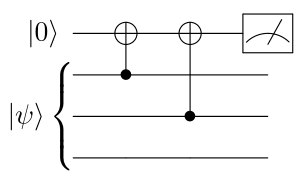

So, to sum it up, these parity measurements yield a two-bit classical result called a ***Syndrome***, indicating precisely which qubit (if any) experienced the error, without altering the encoded logical state. In fact, we are not interested about which qubit flipped, even if it's trivial to determine which was, we are mainly interested in correcting it and obtain the correct information.

For completeness, the measurement outcomes for syndromes and the corresponding corrective actions are summarized below:

This elegant approach allows correcting any single-qubit bit-flip error while preserving the original quantum information encoded.

## 2. Putting Theory into Practice: Our Code Workflow

So, how do we take this abstract idea of quantum error correction that we have just described and actually make it work? 

Below, we break down the code pipeline into a series of clear stages. Each stage builds upon the previous one, taking us from a simple quantum circuit to a robust, error-protected version—and finally, to real performance analysis.

### **2.1 Stage 1: Circuit Analysis**

We start with the original *bare* quantum circuit, the one you’d run if you weren’t worried about errors. Before doing anything else, we analyze its structure for statistical reasons:

- *How many qubits are involved?*

- *Which gates and how many of them are applied?*

This helps us understand what resources we’re starting with, and will later let us compare how much *overhead* error correction introduces.

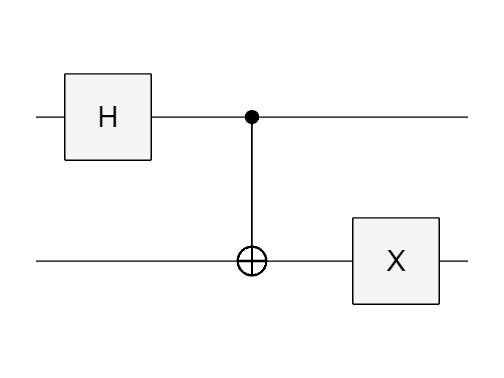

%% Stage 1: Circuit Analysis
function properties = analyzeCircuit(circuit)
    properties.numQubits   = circuit.NumQubits;
    properties.gatesByType = countGates(circuit);
end

function finalTable = countGates(circuit)
    allGates = circuit.Gates;
    n    = numel(allGates);
    types = strings(n,1);
    for k = 1:n
        types(k) = string(allGates(k).Type);

    end

Original Circuit:


    [uTypes, ~, idx] = unique(types);

      numQubits: 2
    gatesByType: [3×2 table]



    counts = accumarray(idx,1);
    finalTable = table(uTypes, counts, 'VariableNames',{'Type','Count'});
end

### **2.2 Stage 2: Encoding with the Repetition Code**

Let’s make our circuit resilient to bit-flips by applying the repetition code.

We use the repetition code to encode each logical qubit across $d$ physical qubits.

This function generates all the CNOT Gates needed to spread each logical qubit’s state across its group of $d$ physical qubits.

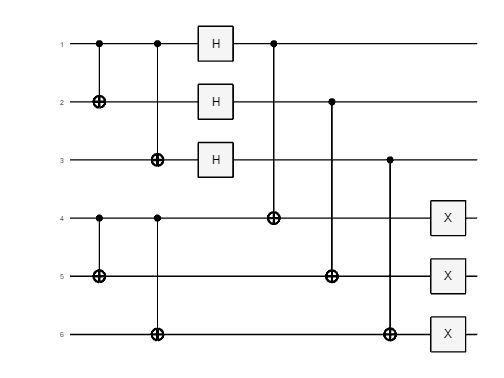

%% Stage 2: Repetition-Code Encoding

function repGates = encodeSingleQubitRepetition(logicalIdx, d)
    base = (logicalIdx-1)*d + 1;
    repGates = quantum.gate.SimpleGate.empty(0,1);

Encoded Circuit:


    for k = 2:d

      numQubits: 6
    gatesByType: [3×2 table]



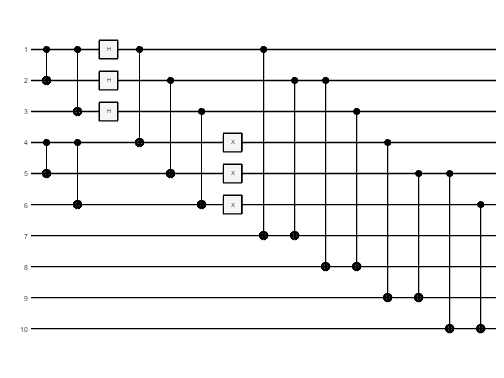

        repGates(end+1,1) = cnotGate(base, base + k - 1);
    end
end

function allQubitsEncoded = encodeAllLogicalQubits(originalCircuit, d)
    nLog = originalCircuit.NumQubits;
    allQubitsEncoded = quantum.gate.SimpleGate.empty(0,1);
    for q = 1:nLog

        allQubitsEncoded = [allQubitsEncoded; encodeSingleQubitRepetition(q, d)];
    end
end


### **2.3 Stage 3: Remapping the Original Gates on the Error-Corrected Circuit**

If the original circuit was performing computation on some qubits, we would kindly have the same operations back on its error-corrected version.

Each gate from the original circuit is **mapped “transversally”** onto all the wires of its corresponding code block. So, a single X gate becomes multiple X gates—one for each physical qubit in the block. Multi-qubit gates (like CNOT) become sets of “parallel” CNOTs. 

%% Stage 3: Remapping Original Gates
function mapped = mapOriginalGates(originalCircuit, d)


Error-correction check for logical |+> = H|0>:


    
    oldG   = originalCircuit.Gates;
    mapped = quantum.gate.SimpleGate.empty(0,1);

    for k = 1:numel(oldG)
        g    = oldG(k);
        ctrl = g.ControlQubits;    % [] or [c]
        tgt  = g.TargetQubits;     % [t] or [t1 t2]
        
        switch numel(ctrl)
          %% Single-qubit gates (H, X, Y, Z, S, T, SX, RX, RY, RZ)
          case 0
            for q = tgt(:).'
              for j = 1:d
                wire = (q-1)*d + j;
                switch g.Type
                  case "h"
                    mapped(end+1,1) = hGate(wire);
                  case "x"
                    mapped(end+1,1) = xGate(wire);
                  case "y"
                    mapped(end+1,1) = yGate(wire);
                  case "z"
                    mapped(end+1,1) = zGate(wire);
                  case "s"

 wire 1 → fidelity = 1.000000
 wire 2 → fidelity = 1.000000
 wire 3 → fidelity = 1.000000


                    mapped(end+1,1) = sGate(wire);
                  case "t"
                    mapped(end+1,1) = tGate(wire);
                  case "sx"
                    mapped(end+1,1) = sxGate(wire);
                  case {"rx","ry","rz"}
                    ang = g.Angles;
                    if g.Type=="rx"
                      mapped(end+1,1) = rxGate(wire, ang);
                    elseif g.Type=="ry"


Qubit overhead: 3.0x


                      mapped(end+1,1) = ryGate(wire, ang);
                    else
                      mapped(end+1,1) = rzGate(wire, ang);
                    end
                  otherwise
                    error("Unsupported single-qubit gate: %s", g.Type);
                end
              end
            end

          %% Single-control gates (CX, CZ, CRX, CRY, CRZ)

Gate‐count Comparison:


          case 1

    Type    Original    Encoded
    ____    ________    _______

    "cx"       1           7   
    "h"        1           3   
    "x"        1           3   



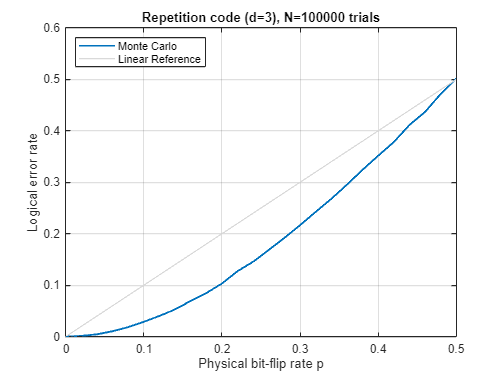

            c = ctrl(1);
            t = tgt(1);
            for j = 1:d
              cw = (c-1)*d + j;
              tw = (t-1)*d + j;
              switch g.Type
                case "cx"
                  mapped(end+1,1) = cnotGate(cw, tw);
                case "cz"
                  mapped(end+1,1) = czGate(cw, tw);
                case "crx"
                  mapped(end+1,1) = crxGate(cw, tw, g.Angles);
                case "cry"
                  mapped(end+1,1) = cryGate(cw, tw, g.Angles);
                case "crz"
                  mapped(end+1,1) = crzGate(cw, tw, g.Angles);
                otherwise
                  error("Unsupported 1-control gate: %s", g.Type);
              end
            end

          %% Two-control Toffoli (CCX)
          case 2
            c1 = ctrl(1);  c2 = ctrl(2);
            t  = tgt(1);
            for j = 1:d
              cw1 = (c1-1)*d + j;
              cw2 = (c2-1)*d + j;
              tw  = (t -1)*d + j;
              mapped(end+1,1) = ccxGate(cw1, cw2, tw);
            end


          otherwise
            error("Gates with %d controls not supported", numel(ctrl));
        end
    end
end


### **2.4 Stage 4: Assembling the Encoded Circuit**

Now we stitch together all those encoding gates and the remapped logical gates to build the full encoded version of our original circuit, acting on many more qubits.

This produces the error-protected version of our original quantum circuit.

%% Stage 4: Build the Encoded Circuit
function encCircuit = applyRepetitionCode(originalCircuit, d)
    nLogical  = originalCircuit.NumQubits;
    nPhysical = nLogical * d;
    encGates   = encodeAllLogicalQubits(originalCircuit, d);
    mapGates   = mapOriginalGates(originalCircuit, d);
    allGates   = [encGates; mapGates];
    encCircuit = quantumCircuit(allGates, nPhysical);
end

### **2.5 Stage 5: Ancilla Allocation & Syndrome Measurement**

*How do we detect errors ****without destroying**** our quantum state?*

We introduce extra qubits—**ancillas**—to measure parities (*syndromes*) between physical qubits in each block.

This step adds a new circuit section that can identify which, if any, qubit suffered a bit-flip error—without collapsing the quantum information itself, as we previously described.

%% Stage 5: Ancilla Allocation & Syndrome Measurement
function [synGates, ancillaWires] = buildSyndromeBlock(nLog, d)

    dataWires   = nLog * d;         % total physical data wires
    totalAnc    = nLog * (d-1);     % allocate (d-1) ancillas per logical qubit
    ancillaWires = dataWires + (1:totalAnc);

    synGates = quantum.gate.SimpleGate.empty(0,1);
    for q = 1:nLog
        % data‐block starts at (q-1)*d + 1
        blockBase = (q-1)*d + 1;
        % ancillas for this block
        ancillaBase   = dataWires + (q-1)*(d-1);
        for k = 1:(d-1)
            aPos = ancillaBase + k;       % Ancilas
            d1   = blockBase + (k-1);     % 1st Data Wire
            d2   = blockBase + k;         % Next Data Wire

            % Parity‐Check: CNOT data → ancilla
            synGates(end+1,1) = cnotGate(d1, aPos);
            synGates(end+1,1) = cnotGate(d2, aPos);
        end
    end
end


### **2.6 Stage 6: Error Injection, Syndrome Extraction, and Correction**

In order to make sure that our error correction is actually repairing errors on physical qubits, according to the inital assumptions (at most one bit-flip error), we provide an easy routine to create errors, detect and correct them.

- **Inject**: We artificially introduce an X (bit-flip) error on any chosen physical qubit.

- **Extract**: We use the syndrome-measurement circuit to detect where the error happened.

- **Correct**: We apply a correction (another X) only to the affected qubit.

%% Stage 6: Error Injection, Syndrome Extraction & Correction

function errCircuit = injectBitFlipError(encCircuit, wire)
    % Introduce a single X (bit-flip) on the specified physical wire
    errCircuit = quantumCircuit([encCircuit.Gates; xGate(wire)], ...
                                encCircuit.NumQubits);
end

function syndrome = measureSyndromeAndDecode(errCircuit, nLog, d)
    % Build and append the CNOT parity‐checks into ancillas
    [synGates, ancVector] = buildSyndromeBlock(nLog, d);
    synCirc = quantumCircuit([errCircuit.Gates; synGates], ...
                             errCircuit.NumQubits + numel(ancVector));

    % Simulate & take one measurement
    qs   = simulate(synCirc);
    shot = randsample(qs,1);
    bits = double(char(shot.MeasuredStates) - '0');

    % Extract only the ancilla bits → syndrome vector
    syndrome = bits(ancVector);
end

function corrCircuit = applySyndromeCorrection(errCircuit, syndrome, nLog, d)
    allGates = errCircuit.Gates;
    corrG    = quantum.gate.SimpleGate.empty(0,1);
    
    % For each logical qubit, decode its (d–1)‐bit Syndrome
    for q = 1:nLog
        base      = (q-1)*d;
        % slice out this block’s syndrome
        syndromeBlock    = syndrome((q-1)*(d-1) + (1:(d-1)));
        % find which physical position k∈1:d triggered it
        errPos    = 0;
        for k = 1:d
            % Expected Outcome: 1’s at position where parity‐check interacts with k
            expectedSyndrome = zeros(1,d-1);
            for i = 1:(d-1)
                if k==i || k==i+1
                    expectedSyndrome(i) = 1;
                end
            end
            if isequal(syndromeBlock, expectedSyndrome)
                errPos = k;
                break;
            end
        end

        % Append a correcting X if an error has been detected
        if errPos>0
            corrG(end+1,1) = xGate(base + errPos);
        end
    end
    
    corrCircuit = quantumCircuit([allGates; corrG], errCircuit.NumQubits);
end

%Helper Functions
function phiL = decodeState(qs, d)
    a = qs.Amplitudes(:);
    phiL = [a(1); a(end)]; phiL = phiL/norm(phiL);
end

function F = pureStateFidelity(a,b)
    F = abs(a' * b)^2;
end

### 2.7 Stage 7: A Complete Workflow Example

Now it’s time to see all the stages combined. We take a concrete quantum circuit—a simple algorithm involving a Hadamard, CNOT, and X gate—and walk it through the full error-correcting pipeline, step by step.

First, we **analyze the original circuit** to see its basic structure. Then, using the *repetition code* with a user-defined **distance** $d$, we encode and protect each logical qubit.

 The *distance* of a code is a key concept: it’s the minimum number of physical qubit errors required to turn one valid codeword into another. More intuitively, a code with distance $d$ can correct up to $t$ errors, where $d=2t+1$. For example, with the familiar three-qubit code $d=3$, we can reliably correct any single bit-flip $t=1$.

Next, we insert **syndrome measurement circuits** using extra (ancilla) qubits, allowing us to detect and locate errors without destroying the encoded quantum information. We visualize each major stage of the process, plotting both the original and encoded circuits, and also highlight how the circuit structure grows as error correction is added.

Finally, by running  a simple **simulation **and** visualizing the result**, we observe the effect of error correction in practice. We see how the logical error rate (the probability that a logical qubit is misread after error correction) depends on the physical error rate and code distance. This allows us to understand both their strengths and limitations.

Through this hands-on example, you’ll gain an intuitive and practical grasp of quantum error correction, see the impact of the distance parameter, and appreciate what’s required to build robust quantum algorithms for the real world!

Feel free to adjust the distance parameter $d$ with other odd values and see how the circuit and the logical error rate is affected by it.

%% Stage 7: A Complete Workflow Example
% Quantum Error Correction via Repetition Code

%% Parameters
d       = 3;             % repetition distance (odd ≥3)
assert(mod(d,2)==1 && d>=3, 'Distance d must be an odd integer ≥3');

%% Sample original circuit (H, CNOT, X)
origGates   = [ hGate(1), cnotGate(1,2), xGate(2) ];
origCircuit = quantumCircuit(origGates, 2);

%% Analyze original circuit
origProps = analyzeCircuit(origCircuit);
figure('Name','Original Circuit');
plot(origCircuit);
disp('Original Circuit:');
disp(origProps);
%% Encode & remap gates transversally
encCircuit = applyRepetitionCode(origCircuit, d);
figure('Name','Encoded Circuit');
plot(encCircuit);
%% Analyze encoded circuit
encProps = analyzeCircuit(encCircuit);
disp('Encoded Circuit:');
disp(encProps);
%% Syndrome–Measurement Block
[nLog,~]    = deal(origCircuit.NumQubits,[]);
[synGates, ancW] = buildSyndromeBlock(nLog, d);
fullCirc    = quantumCircuit([encCircuit.Gates; synGates], nLog*d + numel(ancW));
fig = figure('Name','Encode + Syndrome Block');

plot(fullCirc);
title('Data‐Encode + Parity‐Check');

### 2.8 Stage 8: Fidelity Check

Did we really restore the original logical state?

We decode the corrected state and compare it to the error-free version. A fidelity near 1 means our error correction worked perfectly for that case!

%% Stage 8: Demonstrate correction on each physical qubit
fprintf('\nError-correction check for logical |+> = H|0>:\n');

% Prepare the logical |+> state and its ideal simulated output
qc0   = quantumCircuit(hGate(1), 1);  % single logical qubit
ideal = simulate(qc0);                % 2-amplitude QuantumState

% Encode |+> with the repetition code of distance d
enc1  = applyRepetitionCode(qc0, d);  % now on d physical wires

% Loop over each physical wire, inject X, measure, correct, decode &
% compute fidelity (on a simulated circuit)
for w = 1:d
    err1 = injectBitFlipError(enc1, w); % inject one bit-flip
    
    % extract syndrome and correct
    syn   = measureSyndromeAndDecode(err1, 1, d);
    corr1 = applySyndromeCorrection(err1, syn, 1, d);
    
    % simulate corrected circuit and decode back to 2-amplitude logical state
    st      = simulate(corr1);    
    decoded = decodeState(st, d); 
    
    % compute fidelity against the ideal |+> state
    F = pureStateFidelity(ideal.Amplitudes, decoded);
    fprintf(' wire %d → fidelity = %.6f\n', w, F);
end

### **2.9 Stage 9: Resource Comparison**

Unfortunately, as you may have imagined while reading through the stages, error correction comes with a cost!

While it gives us extra protection against errors, it does so at the price of using more resources. Let's take a closer look at exactly how much extra qubits and gates our encoded, error-corrected circuit consumes compared to the original circuit, which is a trivial operation.

First up is the number of qubits. For a repetition code of distance $d$, every logical qubit gets expanded into $d\;$physical qubits, so the total number of wires in the encoded circuit simply grows by a factor of $d$. And if we’re also adding ancilla qubits for syndrome measurements, the count grows even more. The qubit overhead is simply the ratio of encoded to original qubits, and it’s worth keeping in mind as you dream up bigger quantum computations—the hardware needs to multiply quickly!

But it’s not just about qubits; gate overhead matters too. When we encode our gates transversally (i.e., applying the same operation to each physical copy), a single logical gate gets also copied $d$ times, multiplying the total number of gates in the circuit. On top of that, the error correction procedure introduces a bunch of extra gates: think about all those CNOTs for parity checks.

The code below displays a table comparing the number of each type of gate before and after error correction. It’s a great way to see, at a glance, just how much heavier your circuit has become—and why scaling up quantum error-correcting codes is a real engineering challenge. More protection means more hardware, and as in every engineering field, there’s always a trade-off.

%% Stage 9: Resource Comparison
qubitOverhead = encProps.numQubits / origProps.numQubits;
fprintf('\nQubit overhead: %.1fx\n', qubitOverhead);
origTbl = countGates(origCircuit);
encTbl  = countGates(encCircuit);
allT    = union(origTbl.Type, encTbl.Type);
comp    = table(allT, zeros(numel(allT),1), zeros(numel(allT),1), ...
           'VariableNames',{'Type','Original','Encoded'});
for i=1:height(comp)
  t = comp.Type{i};
  comp.Original(i) = sum(origTbl.Count(origTbl.Type==t));
  comp.Encoded (i) = sum(encTbl.Count(encTbl.Type==t));
end
disp('Gate‐count Comparison:');
disp(comp);

### **2.10 Stage 10: Monte Carlo Simulation of Logical Error Rate**

But, *how well does this code protect against errors, statistically?*

To get an intuitive sense of just how much help the repetition code really gives us, let’s simulate thousands of random error patterns and see how things play out. In the plot below, we show how the logical error rate—meaning, the chance that we *still* end up with the wrong answer after applying our error correction—changes as we increase the physical bit-flip probability $p$.

For a code of distance $d$, the logical error rate is simply the probability that more than half the physical qubits in a code block flip. If every qubit flips independently with probability $p$, the formula is:

$P_{\mathrm{logical}} \left(p\right)=\sum_{k=m+1}^d \mathrm{Binomial}\left(d,k\right)\;p^k \;{\left(1-p\right)}^{d-k}$, where $m=\left\lfloor \frac{d}{2}\right\rfloor$

The blue curve shows the simulated *logical error rate*, while the gray straight line is what you’d get *without* any error correction—just sending a single bit and hoping for the best. What you’ll notice is that, for small $p$, error correction really does its job, squashing the logical error rate down. But as $p$ gets closer to 0.5, even the code can’t keep up—eventually, the correction starts to fail more often than not.

This is a visual reminder that, while quantum error correction is powerful, it isn’t magic. It buys us robustness, but only if the underlying hardware is reliable enough. 

Try changing $d$ in the code and watch how the curve responds!

%% Stage 10: Monte Carlo Simulation of Logical-Error Rate

pVec    = 0:0.02:0.5;    % physical bit-flip rates
Ntrials = 1e5;           % trials per p

m = floor(d/2);
logicalErr = zeros(size(pVec));
for i = 1:numel(pVec)
  p = pVec(i);
  flips = rand(d, Ntrials) < p;           % d×Ntrials flips
  logicalErr(i) = mean( sum(flips,1) > m );% majority-fails → logical error
end

figure('Name','Logical vs Physical Error Rate');
plot(pVec, logicalErr, 'LineWidth',1.5);
hold on;
plot(pVec, pVec,    'Color',[0.85 0.85 0.85], 'LineWidth',1);
hold off;
xlabel('Physical bit-flip rate p');
ylabel('Logical error rate');
title(sprintf('Repetition code (d=%d), N=%d trials', d, Ntrials));
legend({'Monte Carlo','Linear Reference'}, 'Location','northwest');
grid on;

## `Acknowledgments`

### `1 Resources`

Marco Venere, *“Quantum Computing - A Practical Perspective”, Politecnico di Milano*.

Nielsen, M. A., Chuang, I. L. *“Quantum Computation and Quantum Information. Cambridge University Press”*.

### `2 Articles `

[1] Shor, P. W. (1995). [Scheme for reducing decoherence in quantum computer memory.](doi:10.1103/PhysRevA.52.R2493)

[2] J. Roffe (2019) [Quantum Error Correction: An Introductory Guide](https://arxiv.org/abs/1907.11157)

### `3 Websites `

[Arthur Pesah - The stabilizer trilogy I — Stabilizer codes](https://arthurpesah.me/blog/2023-01-31-stabilizer-formalism-1/)

[IBM - Corrrecting Quantum Errors](https://learning.quantum.ibm.com/course/foundations-of-quantum-error-correction/correcting-quantum-errors)